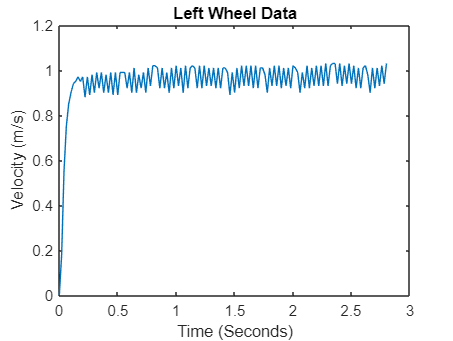

close all
clear all
clc

wheel_data = [0.00,0.00;
0.18,0.18;
0.55,0.57;
0.75,0.75;
0.85,0.84;
0.90,0.88;
0.94,0.92;
0.95,0.92;
0.97,0.93;
0.95,0.93;
0.97,0.93;
0.88,0.86;
0.97,0.94;
0.89,0.88;
0.98,0.95;
0.90,0.86;
0.99,0.95;
0.92,0.88;
0.99,0.95;
0.90,0.86;
0.98,0.94;
0.90,0.88;
0.99,0.95;
0.89,0.88;
0.99,0.95;
0.89,0.86;
0.99,0.97;
0.99,0.95;
0.99,0.97;
0.92,0.88;
0.99,0.97;
0.90,0.86;
1.01,0.97;
0.90,0.86;
0.98,0.95;
0.92,0.88;
0.99,0.97;
0.90,0.88;
1.01,0.97;
0.93,0.89;
1.02,0.97;
1.02,0.97;
1.01,0.97;
0.92,0.86;
1.01,0.97;
0.92,0.88;
0.99,0.95;
0.90,0.86;
1.01,0.97;
0.92,0.88;
1.02,0.97;
0.93,0.88;
1.01,0.97;
0.90,0.88;
1.02,0.98;
0.92,0.88;
1.01,0.98;
1.02,0.97;
1.01,0.97;
0.92,0.88;
1.02,0.97;
0.92,0.88;
1.02,0.97;
0.93,0.88;
1.01,0.97;
0.93,0.89;
1.01,0.97;
0.92,0.86;
1.01,0.97;
0.92,0.89;
1.01,0.97;
1.01,0.97;
0.99,0.95;
0.89,0.88;
0.99,0.97;
0.90,0.88;
1.01,0.98;
0.92,0.88;
1.02,0.98;
0.93,0.89;
1.02,0.97;
0.93,0.88;
1.02,0.98;
0.92,0.88;
1.02,0.97;
0.92,0.89;
1.01,0.97;
1.01,0.97;
0.98,0.94;
0.90,0.88;
1.01,0.97;
0.93,0.89;
1.02,0.98;
0.93,0.89;
1.02,0.98;
0.92,0.89;
1.01,0.97;
0.93,0.89;
1.01,0.97;
0.92,0.89;
1.02,0.99;
1.01,0.98;
0.99,0.95;
0.90,0.88;
0.99,0.97;
0.92,0.89;
1.02,0.98;
0.92,0.89;
1.01,0.98;
0.93,0.89;
1.02,0.98;
0.93,0.89;
1.02,0.98;
0.93,0.88;
1.03,0.98;
0.93,0.90;
1.02,0.98;
1.03,0.99;
1.03,0.97;
0.94,0.89;
1.03,0.98;
0.93,0.89;
1.02,0.99;
0.94,0.90;
1.03,0.99;
0.94,0.90;
1.02,0.98;
0.92,0.89;
1.01,0.98;
0.92,0.90;
1.01,0.98;
1.02,0.97;
0.98,0.95;
0.90,0.88;
1.01,0.98;
0.92,0.90;
1.01,0.97;
0.93,0.89;
1.02,0.99;
0.94,0.90;
1.03,0.99];
left_vel = wheel_data(:, 1);
right_vel = wheel_data(:, 2);

t = 0:0.02:(length(wheel_data)*0.02-0.02);
plot(t, wheel_data(:, 1));
title("Left Wheel Data")
xlabel("Time (Seconds)")
ylabel("Velocity (m/s)")

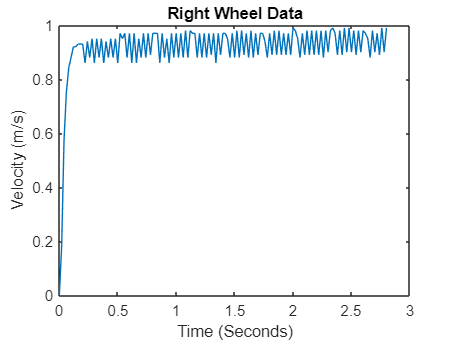

% curveFitter

plot(t, wheel_data(:, 2));
title("Right Wheel Data")
xlabel("Time (Seconds)")
ylabel("Velocity (m/s)")

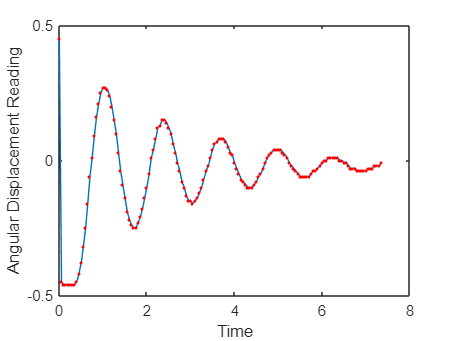

% USE THIS TO FIND NATURAL FREQUENCY
close all
clear all
clc

angular_displacement = [
0.45
-0.45
-0.46
-0.46
-0.46
-0.46
-0.46
-0.46
-0.45
-0.42
-0.38
-0.32
-0.25
-0.16
-0.06
0.01
0.09
0.16
0.21
0.25
0.27
0.27
0.26
0.24
0.20
0.15
0.10
0.03
-0.04
-0.09
-0.14
-0.19
-0.22
-0.24
-0.25
-0.25
-0.23
-0.21
-0.18
-0.14
-0.10
-0.05
0.01
0.04
0.08
0.12
0.13
0.15
0.15
0.14
0.12
0.10
0.06
0.03
-0.01
-0.04
-0.08
-0.10
-0.13
-0.15
-0.15
-0.16
-0.15
-0.14
-0.12
-0.10
-0.07
-0.04
-0.02
0.01
0.04
0.06
0.07
0.08
0.08
0.08
0.07
0.05
0.03
0.02
-0.01
-0.03
-0.05
-0.07
-0.08
-0.09
-0.10
-0.10
-0.10
-0.09
-0.08
-0.06
-0.05
-0.03
-0.01
0.01
0.02
0.03
0.04
0.04
0.04
0.04
0.03
0.02
0.01
-0.01
-0.02
-0.03
-0.04
-0.05
-0.06
-0.06
-0.06
-0.06
-0.06
-0.05
-0.04
-0.04
-0.03
-0.02
-0.01
-0.00
0.00
0.01
0.01
0.01
0.01
0.01
0.00
0.00
-0.01
-0.01
-0.02
-0.03
-0.03
-0.03
-0.04
-0.04
-0.04
-0.04
-0.04
-0.03
-0.03
-0.03
-0.02
-0.02
-0.02
-0.01];

t_gyro= 0:0.05:(length(angular_displacement)*0.05-0.05);
plot(t_gyro, angular_displacement)
xlabel("Time")
ylabel("Angular Displacement Reading"); hold on
plot(t_gyro, angular_displacement, '.r')


% Find locations of peaks to find natural frequency
[peaks, loc] = findpeaks(angular_displacement);
loc = loc .* 0.05;  % loc is index
seconds_per_rev = mean(diff(loc));  % loc is now time
natural_frequency = (1/seconds_per_rev) * 2*pi

natural_frequency = 4.8801


g = 9.81;
l_eff = g/(natural_frequency^2) %m

l_eff = 0.4119